# Frequency Modulation ( FM )

% Author Name : Atmanand Manoj Gauns
% Affiliation : Roll No.: 201104012
%               Branch : E&TC GCE
%               Year : TE Sem- 5 2021-22 


## Variables

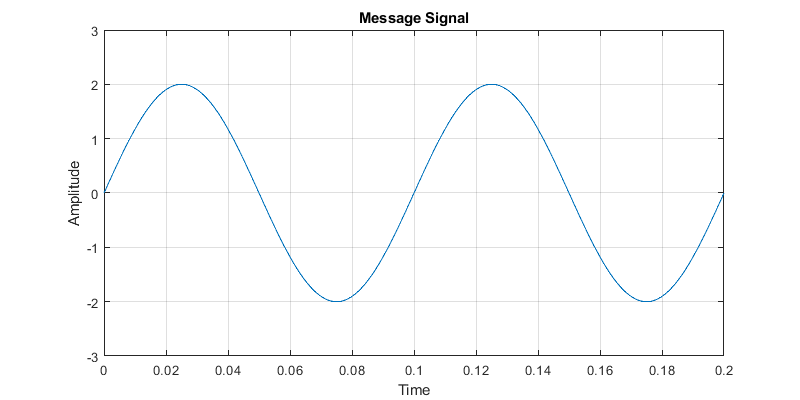

clc;
clear;
Vm=2;
Vc=5;
fm=10; % message frequency
fc=500; % carrier frequency
fs=10*fc; % sampling frequency
mf=20;
endpoint=5;
t=0:1/fs:endpoint; %% Time series index
l=length(t);
i=(-l/2:1:l/2-1).*2/10; %% frequency series index
% kf=10; % Sensitivity factor
% Frequency Deviation = mf*fm
fd=mf/fm;

%Message Signal
f0=figure;
v_m=Vm*sin(2*pi*fm*t);
plot(t,v_m);
title("Message Signal");
xlabel('Time');
ylabel('Amplitude');
set(f0,'Position',[0 0 800 400]);
grid on;
xlim([0.000 0.200]);
ylim([-Vm-1 Vm+1]);

## FM Signal

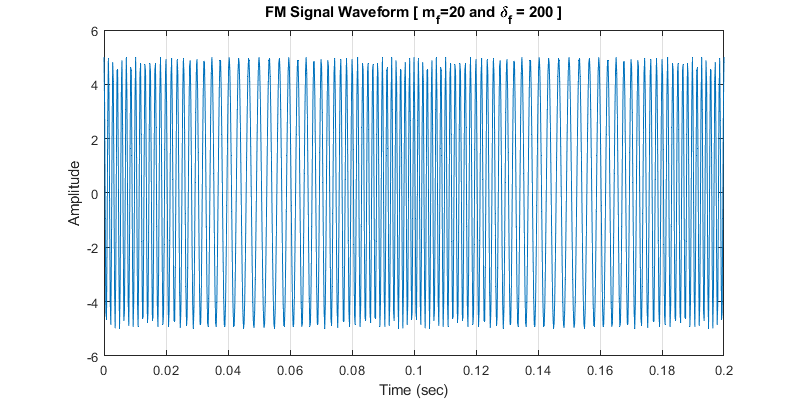

v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
f1=figure;
plot(t,v_fm);
title(['FM Signal Waveform [ m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' ]']);
xlabel('Time (sec)');
ylabel('Amplitude');
set(f1,'Position',[0 0 800 400]);
grid on;
xlim([0.000 0.200]);
ylim([-Vc-1 Vc+1]);

## Modulation Index = 0.5 

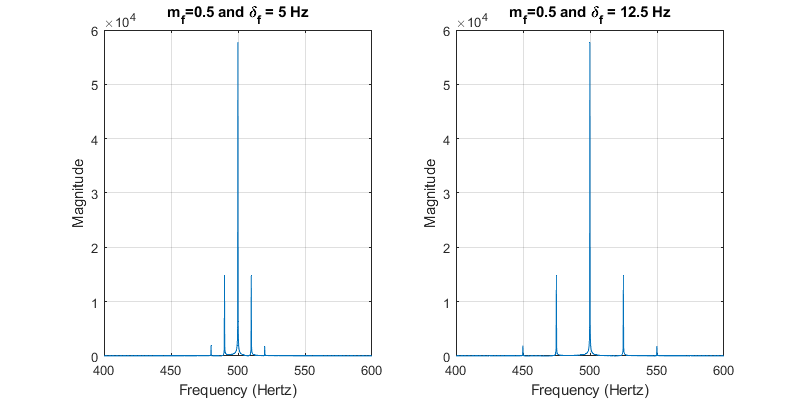

%                   Deflection Coefficient =5 Hz :
mf=0.5;
fm=10;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
figure(1);
subplot(1,2,1);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;
xlim([fc-200*mf fc+200*mf]);
ylim([0 60000]);


%                   Deflection Coefficient =12.5 Hz :
mf=0.5;
fm=25;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
figure(1);
subplot(1,2,2);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;
xlim([fc-200*mf fc+200*mf]);
ylim([0 60000]);

## Modulation Index = 2.5 

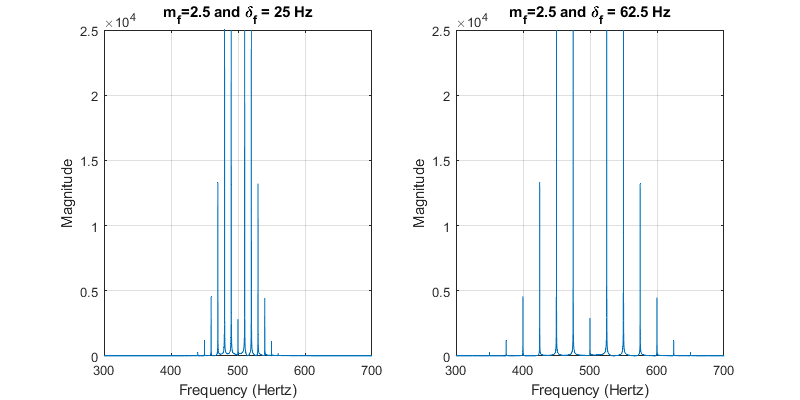

%                       Deflection Coefficient =25 Hz :
mf=2.5;
fm=10;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
figure(2);
subplot(1,2,1);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;

%                       Deflection Coefficient =62.5 Hz :
fm=25;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
figure(2);
subplot(1,2,2);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;

subplot(1,2,1);
xlim([fc-200 fc+200]);
ylim([0 25000]);
subplot(1,2,2);
xlim([fc-200 fc+200]);
ylim([0 25000]);

##   Modulation Index = 5

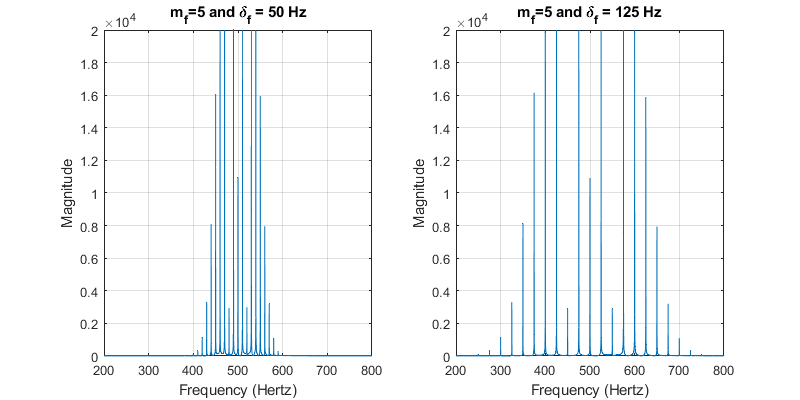

%                       Deflection Coefficient =50 Hz :
mf=5;
fm=10;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
f3=figure;
subplot(1,2,1);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;
set(f3,'Position',[0 0 800 400]);
xlim([fc-60*mf fc+60*mf]);
ylim([0 20000]);


%                       Deflection Coefficient =125 Hz :
mf=5;
fm=25;
v_fm=Vc*cos(2*pi*fc*t+mf*sin(2*pi*fm*t));
spec_fm=abs(fftshift(fft(v_fm)));
subplot(1,2,2);
plot(i,spec_fm);
title(['m_{f}=',num2str(mf),' and \delta_{f} = ',num2str(mf*fm),' Hz']);
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
grid on;
set(f3,'Position',[0 0 800 400]);
xlim([fc-60*mf fc+60*mf]);
ylim([0 20000]);